Load data

load dataset/pagerank_adj.mat

a) Verify that each column in A sum to 1. What is the importance of this property for the Google PageRank algorithm?

%compute link matrix
A = J;
for i = 1:size(J,1)
    A(:,i) = A(:,i)./sum(A(:,i));
end 

%Compute sum of each column
B = zeros(1, size(J,1));
for i = 1:size(J,1)
    B(i) = sum(A(:,i));
end
B

B =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


All columns sum to 1.

Since each column refers to a source webpage, since each column sums to 1, this means that each webpage will move to another. Therefore no dangling pages.

b) Implement the power iteration algorithm. Run the algorithm for 10 iterations and plot log(e(k+1)) versus k.

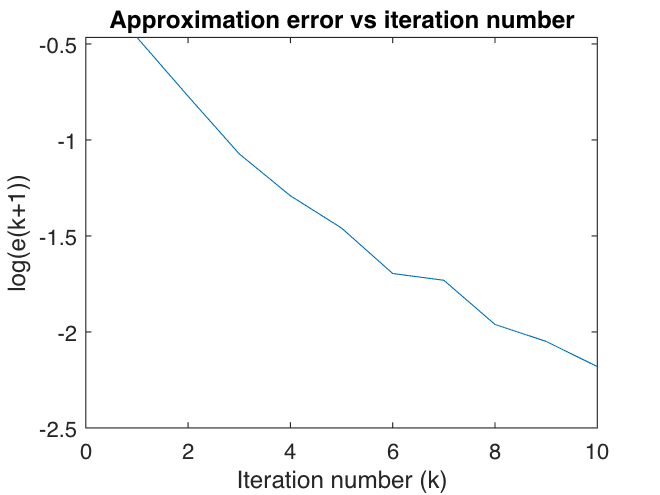

%define x
x = ones(size(J,1), 1);
error = zeros(10,1);

for k = 1:10
    y = A*x;
    x = y/(norm(y));
    error(k) = norm(A*x-x);
end

x = 1:10;
plot(x, log(error));
xlabel("Iteration number (k)");
ylabel("log(e(k+1))");
title("Approximation error vs iteration number");

c) Implement the shift-invert power iteration method.

s = 0.99;
n = size(A,1);
x = ones(n, 1);
error = zeros(10,1);

for k = 1:10
    y = (A - s*eye(n))\x;
    x = y/norm(y);
    error(k) = norm(A*x-x);
end

x = 1:10;
plot(x, log(error));
hold on

Implement Raleigh quotient iteration algorithm.

s = 0.99;
n = size(A,1);
x = ones(n,1);
error = zeros(10,1);

for k = 1:2
    y = (A - s*eye(n))\x;
    x = y./norm(y);
    error(k) = norm(A*x-x);
end

for k = 3:10
    s = (x'*A*x)/(x'*x);
    y = (A - s*eye(n))\x;
    x = y/norm(y);
    error(k) = norm(A*x-x);
end


x = 1:10;
plot(x, log(error));

Plot power iteration.

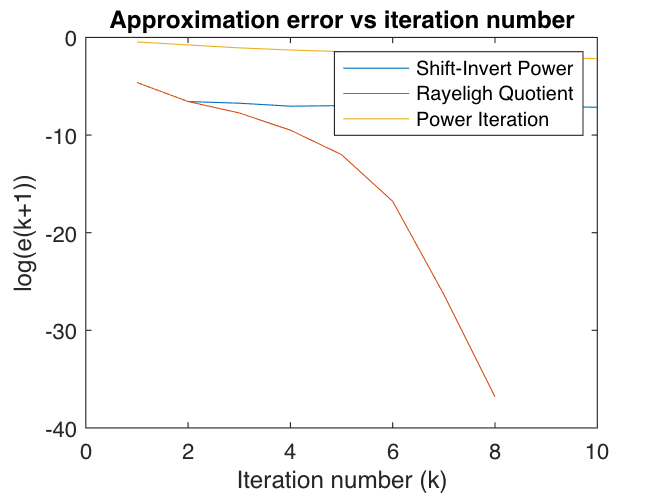

x = ones(size(J,1), 1);
error = zeros(10,1);

for k = 1:10
    y = A*x;
    x = y./(norm(y));
    error(k) = norm(A*x-x);
end

x_rng = 1:10;
plot(x_rng, log(error));
xlabel("Iteration number (k)");
ylabel("log(e(k+1))");
title("Approximation error vs iteration number");
legend('Shift-Invert Power','Rayeligh Quotient','Power Iteration')
hold off

Yes. These results are consistent with example 7.1.

d) List the (page index, PageRank score) pairs of the top 5 and bottom 5 pages according to your PageRank scores.

[out,idx] = sort(x);
disp("Lowest 5 PageRank scores and indices")

Lowest 5 PageRank scores and indices


out(1:5)

ans =      0
     0
     0
     0
     0


idx(1:5)

ans =      1
     3
     4
     5
    10



disp("Highest 5 PageRank scores and indices")

Highest 5 PageRank scores and indices


[out,idx] = sort(x, 'descend');
out(1:5)

ans =     0.4394
    0.3296
    0.3073
    0.2996
    0.2751


idx(1:5)

ans =      2
    35
    36
    58
    49
